# **LAB: CWRU Bearing Fault Diagnosis**

**Name: Kim Inyeop  **

### Drive End Bearing Experiment

## 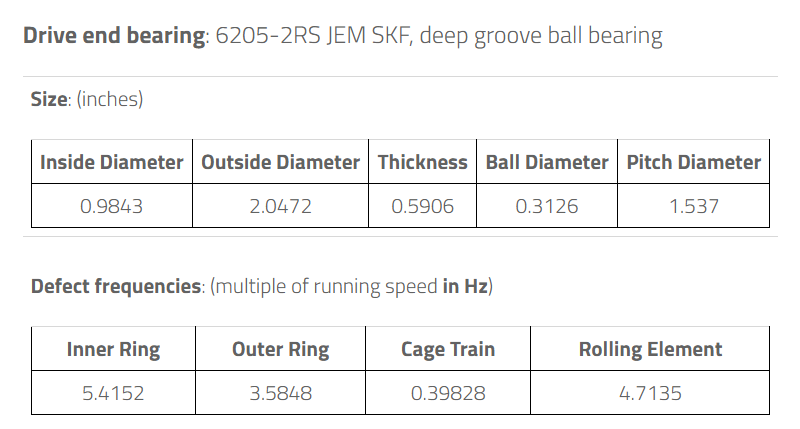

## Load Dataset

close all
clear
fileList = {
"../../Dataset/Raw_data/ball_007_0hp.mat"
"../../Dataset/Raw_data/ball_007_1hp.mat"
"../../Dataset/Raw_data/ball_007_2hp.mat"
"../../Dataset/Raw_data/ball_007_3hp.mat"
"../../Dataset/Raw_data/ball_014_0hp.mat"
"../../Dataset/Raw_data/ball_014_1hp.mat"
"../../Dataset/Raw_data/ball_014_2hp.mat"
"../../Dataset/Raw_data/ball_014_3hp.mat"
"../../Dataset/Raw_data/ball_021_0hp.mat"
"../../Dataset/Raw_data/ball_021_1hp.mat"
"../../Dataset/Raw_data/ball_021_2hp.mat"
"../../Dataset/Raw_data/ball_021_3hp.mat"

"../../Dataset/Raw_data/inner_007_0hp.mat"
"../../Dataset/Raw_data/inner_007_1hp.mat"
"../../Dataset/Raw_data/inner_007_2hp.mat"
"../../Dataset/Raw_data/inner_007_3hp.mat"
"../../Dataset/Raw_data/inner_014_0hp.mat"
"../../Dataset/Raw_data/inner_014_1hp.mat"
"../../Dataset/Raw_data/inner_014_2hp.mat"
"../../Dataset/Raw_data/inner_014_3hp.mat"
"../../Dataset/Raw_data/inner_021_0hp.mat"
"../../Dataset/Raw_data/inner_021_1hp.mat"
"../../Dataset/Raw_data/inner_021_2hp.mat"
"../../Dataset/Raw_data/inner_021_3hp.mat"

"../../Dataset/Raw_data/normal_0hp.mat"
"../../Dataset/Raw_data/normal_1hp.mat"
"../../Dataset/Raw_data/normal_2hp.mat"
"../../Dataset/Raw_data/normal_3hp.mat"

"../../Dataset/Raw_data/outer_007_0hp.mat"
"../../Dataset/Raw_data/outer_007_1hp.mat"
"../../Dataset/Raw_data/outer_007_2hp.mat"
"../../Dataset/Raw_data/outer_007_3hp.mat"
"../../Dataset/Raw_data/outer_014_0hp.mat"
"../../Dataset/Raw_data/outer_014_1hp.mat"
"../../Dataset/Raw_data/outer_014_2hp.mat"
"../../Dataset/Raw_data/outer_014_3hp.mat"
"../../Dataset/Raw_data/outer_021_0hp.mat"
"../../Dataset/Raw_data/outer_021_1hp.mat"
"../../Dataset/Raw_data/outer_021_2hp.mat"
"../../Dataset/Raw_data/outer_021_3hp.mat"
};

for i = 1:length(fileList)
    fname = fileList{i};
    fprintf("Loading %s ...\n", fname);

    load(fname);  % ← 변수명 그대로 Workspace에 로드됨

    % 변수 확인(optional)
    S = load(fname);
    vars = fieldnames(S);
    fprintf("  → 포함된 변수명: %s\n", vars{1});
end

Loading ../../Dataset/Raw_data/ball_007_0hp.mat ...


  → 포함된 변수명: X118_DE_time


Loading ../../Dataset/Raw_data/ball_007_1hp.mat ...


  → 포함된 변수명: X119_DE_time


Loading ../../Dataset/Raw_data/ball_007_2hp.mat ...


  → 포함된 변수명: X120_DE_time


Loading ../../Dataset/Raw_data/ball_007_3hp.mat ...


  → 포함된 변수명: X121_DE_time


Loading ../../Dataset/Raw_data/ball_014_0hp.mat ...


  → 포함된 변수명: X185_DE_time


Loading ../../Dataset/Raw_data/ball_014_1hp.mat ...


  → 포함된 변수명: X186_DE_time


Loading ../../Dataset/Raw_data/ball_014_2hp.mat ...


  → 포함된 변수명: X187_DE_time


Loading ../../Dataset/Raw_data/ball_014_3hp.mat ...


  → 포함된 변수명: X188_DE_time


Loading ../../Dataset/Raw_data/ball_021_0hp.mat ...


  → 포함된 변수명: X222_DE_time


Loading ../../Dataset/Raw_data/ball_021_1hp.mat ...


  → 포함된 변수명: X223_DE_time


Loading ../../Dataset/Raw_data/ball_021_2hp.mat ...


  → 포함된 변수명: X224_DE_time


Loading ../../Dataset/Raw_data/ball_021_3hp.mat ...


  → 포함된 변수명: X225_DE_time


Loading ../../Dataset/Raw_data/inner_007_0hp.mat ...


  → 포함된 변수명: X105_DE_time


Loading ../../Dataset/Raw_data/inner_007_1hp.mat ...


  → 포함된 변수명: X106_DE_time


Loading ../../Dataset/Raw_data/inner_007_2hp.mat ...


  → 포함된 변수명: X107_DE_time


Loading ../../Dataset/Raw_data/inner_007_3hp.mat ...


  → 포함된 변수명: X108_DE_time


Loading ../../Dataset/Raw_data/inner_014_0hp.mat ...


  → 포함된 변수명: X169_DE_time


Loading ../../Dataset/Raw_data/inner_014_1hp.mat ...


  → 포함된 변수명: X170_DE_time


Loading ../../Dataset/Raw_data/inner_014_2hp.mat ...


  → 포함된 변수명: X171_DE_time


Loading ../../Dataset/Raw_data/inner_014_3hp.mat ...


  → 포함된 변수명: X172_DE_time


Loading ../../Dataset/Raw_data/inner_021_0hp.mat ...


  → 포함된 변수명: X209_DE_time


Loading ../../Dataset/Raw_data/inner_021_1hp.mat ...


  → 포함된 변수명: X210_DE_time


Loading ../../Dataset/Raw_data/inner_021_2hp.mat ...


  → 포함된 변수명: X211_DE_time


Loading ../../Dataset/Raw_data/inner_021_3hp.mat ...


  → 포함된 변수명: X212_DE_time


Loading ../../Dataset/Raw_data/normal_0hp.mat ...


  → 포함된 변수명: X097_DE_time


Loading ../../Dataset/Raw_data/normal_1hp.mat ...


  → 포함된 변수명: X098_DE_time


Loading ../../Dataset/Raw_data/normal_2hp.mat ...


  → 포함된 변수명: ans


Loading ../../Dataset/Raw_data/normal_3hp.mat ...


  → 포함된 변수명: X100_DE_time


Loading ../../Dataset/Raw_data/outer_007_0hp.mat ...


  → 포함된 변수명: X130_DE_time


Loading ../../Dataset/Raw_data/outer_007_1hp.mat ...


  → 포함된 변수명: X131_DE_time


Loading ../../Dataset/Raw_data/outer_007_2hp.mat ...


  → 포함된 변수명: X132_DE_time


Loading ../../Dataset/Raw_data/outer_007_3hp.mat ...


  → 포함된 변수명: X133_DE_time


Loading ../../Dataset/Raw_data/outer_014_0hp.mat ...


  → 포함된 변수명: X197_DE_time


Loading ../../Dataset/Raw_data/outer_014_1hp.mat ...


  → 포함된 변수명: X198_DE_time


Loading ../../Dataset/Raw_data/outer_014_2hp.mat ...


  → 포함된 변수명: X199_DE_time


Loading ../../Dataset/Raw_data/outer_014_3hp.mat ...


  → 포함된 변수명: X200_DE_time


Loading ../../Dataset/Raw_data/outer_021_0hp.mat ...


  → 포함된 변수명: X237_DE_time


Loading ../../Dataset/Raw_data/outer_021_1hp.mat ...


  → 포함된 변수명: X234_DE_time


Loading ../../Dataset/Raw_data/outer_021_2hp.mat ...


  → 포함된 변수명: X235_DE_time


Loading ../../Dataset/Raw_data/outer_021_3hp.mat ...


  → 포함된 변수명: X236_DE_time


## **Preprocessing**

ballFiles = {
"../../Dataset/Raw_data/ball_007_0hp.mat"
"../../Dataset/Raw_data/ball_007_1hp.mat"
"../../Dataset/Raw_data/ball_007_2hp.mat"
"../../Dataset/Raw_data/ball_007_3hp.mat"
"../../Dataset/Raw_data/ball_014_0hp.mat"
"../../Dataset/Raw_data/ball_014_1hp.mat"
"../../Dataset/Raw_data/ball_014_2hp.mat"
"../../Dataset/Raw_data/ball_014_3hp.mat"
"../../Dataset/Raw_data/ball_021_0hp.mat"
"../../Dataset/Raw_data/ball_021_1hp.mat"
"../../Dataset/Raw_data/ball_021_2hp.mat"
"../../Dataset/Raw_data/ball_021_3hp.mat"

"../../Dataset/Raw_data/inner_007_0hp.mat"
"../../Dataset/Raw_data/inner_007_1hp.mat"
"../../Dataset/Raw_data/inner_007_2hp.mat"
"../../Dataset/Raw_data/inner_007_3hp.mat"
"../../Dataset/Raw_data/inner_014_0hp.mat"
"../../Dataset/Raw_data/inner_014_1hp.mat"
"../../Dataset/Raw_data/inner_014_2hp.mat"
"../../Dataset/Raw_data/inner_014_3hp.mat"
"../../Dataset/Raw_data/inner_021_0hp.mat"
"../../Dataset/Raw_data/inner_021_1hp.mat"
"../../Dataset/Raw_data/inner_021_2hp.mat"
"../../Dataset/Raw_data/inner_021_3hp.mat"

"../../Dataset/Raw_data/normal_0hp.mat"
"../../Dataset/Raw_data/normal_1hp.mat"
"../../Dataset/Raw_data/normal_2hp.mat"
"../../Dataset/Raw_data/normal_3hp.mat"

"../../Dataset/Raw_data/outer_007_0hp.mat"
"../../Dataset/Raw_data/outer_007_1hp.mat"
"../../Dataset/Raw_data/outer_007_2hp.mat"
"../../Dataset/Raw_data/outer_007_3hp.mat"
"../../Dataset/Raw_data/outer_014_0hp.mat"
"../../Dataset/Raw_data/outer_014_1hp.mat"
"../../Dataset/Raw_data/outer_014_2hp.mat"
"../../Dataset/Raw_data/outer_014_3hp.mat"
"../../Dataset/Raw_data/outer_021_0hp.mat"
"../../Dataset/Raw_data/outer_021_1hp.mat"
"../../Dataset/Raw_data/outer_021_2hp.mat"
"../../Dataset/Raw_data/outer_021_3hp.mat"
};

for n = 1:length(ballFiles)
    
    file = ballFiles{n};
    fprintf("\n=== Loading %s ===\n", file);

    S = load(file);
    vars = fieldnames(S);

    DE = []; FE = []; BA = []; RPM = [];

    for i = 1:length(vars)
        v = vars{i};
        if contains(v, "_DE_time")
            DE = S.(v);
        elseif contains(v, "_FE_time")
            FE = S.(v);
        elseif contains(v, "_BA_time")
            BA = S.(v);
        elseif endsWith(v, "RPM")
            RPM = S.(v);
        end
    end

    fprintf("DE length = %d\n", length(DE));
    fprintf("FE length = %d\n", length(FE));
    fprintf("BA length = %d\n", length(BA));
end


=== Loading ../../Dataset/Raw_data/ball_007_0hp.mat ===


DE length = 122571


FE length = 122571


BA length = 122571



=== Loading ../../Dataset/Raw_data/ball_007_1hp.mat ===


DE length = 121410


FE length = 121410


BA length = 121410



=== Loading ../../Dataset/Raw_data/ball_007_2hp.mat ===


DE length = 121556


FE length = 121556


BA length = 121556



=== Loading ../../Dataset/Raw_data/ball_007_3hp.mat ===


DE length = 121556


FE length = 121556


BA length = 121556



=== Loading ../../Dataset/Raw_data/ball_014_0hp.mat ===


DE length = 121846


FE length = 121846


BA length = 121846



=== Loading ../../Dataset/Raw_data/ball_014_1hp.mat ===


DE length = 122136


FE length = 122136


BA length = 122136



=== Loading ../../Dataset/Raw_data/ball_014_2hp.mat ===


DE length = 121991


FE length = 121991


BA length = 121991



=== Loading ../../Dataset/Raw_data/ball_014_3hp.mat ===


DE length = 122136


FE length = 122136


BA length = 122136



=== Loading ../../Dataset/Raw_data/ball_021_0hp.mat ===


DE length = 121991


FE length = 121991


BA length = 121991



=== Loading ../../Dataset/Raw_data/ball_021_1hp.mat ===


DE length = 121701


FE length = 121701


BA length = 121701



=== Loading ../../Dataset/Raw_data/ball_021_2hp.mat ===


DE length = 122136


FE length = 122136


BA length = 122136



=== Loading ../../Dataset/Raw_data/ball_021_3hp.mat ===


DE length = 122136


FE length = 122136


BA length = 122136



=== Loading ../../Dataset/Raw_data/inner_007_0hp.mat ===


DE length = 121265


FE length = 121265


BA length = 121265



=== Loading ../../Dataset/Raw_data/inner_007_1hp.mat ===


DE length = 121991


FE length = 121991


BA length = 121991



=== Loading ../../Dataset/Raw_data/inner_007_2hp.mat ===


DE length = 122136


FE length = 122136


BA length = 122136



=== Loading ../../Dataset/Raw_data/inner_007_3hp.mat ===


DE length = 122917


FE length = 122917


BA length = 122917



=== Loading ../../Dataset/Raw_data/inner_014_0hp.mat ===


DE length = 121846


FE length = 121846


BA length = 121846



=== Loading ../../Dataset/Raw_data/inner_014_1hp.mat ===


DE length = 121846


FE length = 121846


BA length = 121846



=== Loading ../../Dataset/Raw_data/inner_014_2hp.mat ===


DE length = 121846


FE length = 121846


BA length = 121846



=== Loading ../../Dataset/Raw_data/inner_014_3hp.mat ===


DE length = 121701


FE length = 121701


BA length = 121701



=== Loading ../../Dataset/Raw_data/inner_021_0hp.mat ===


DE length = 122136


FE length = 122136


BA length = 122136



=== Loading ../../Dataset/Raw_data/inner_021_1hp.mat ===


DE length = 121556


FE length = 121556


BA length = 121556



=== Loading ../../Dataset/Raw_data/inner_021_2hp.mat ===


DE length = 121846


FE length = 121846


BA length = 121846



=== Loading ../../Dataset/Raw_data/inner_021_3hp.mat ===


DE length = 121991


FE length = 121991


BA length = 121991



=== Loading ../../Dataset/Raw_data/normal_0hp.mat ===


DE length = 243938


FE length = 243938


BA length = 0



=== Loading ../../Dataset/Raw_data/normal_1hp.mat ===


DE length = 483903


FE length = 483903


BA length = 0



=== Loading ../../Dataset/Raw_data/normal_2hp.mat ===


DE length = 485063


FE length = 485063


BA length = 0



=== Loading ../../Dataset/Raw_data/normal_3hp.mat ===


DE length = 485643


FE length = 485643


BA length = 0



=== Loading ../../Dataset/Raw_data/outer_007_0hp.mat ===


DE length = 121991


FE length = 121991


BA length = 121991



=== Loading ../../Dataset/Raw_data/outer_007_1hp.mat ===


DE length = 122426


FE length = 122426


BA length = 122426



=== Loading ../../Dataset/Raw_data/outer_007_2hp.mat ===


DE length = 121410


FE length = 121410


BA length = 121410



=== Loading ../../Dataset/Raw_data/outer_007_3hp.mat ===


DE length = 122571


FE length = 122571


BA length = 122571



=== Loading ../../Dataset/Raw_data/outer_014_0hp.mat ===


DE length = 121846


FE length = 121846


BA length = 121846



=== Loading ../../Dataset/Raw_data/outer_014_1hp.mat ===


DE length = 122136


FE length = 122136


BA length = 122136



=== Loading ../../Dataset/Raw_data/outer_014_2hp.mat ===


DE length = 121846


FE length = 121846


BA length = 121846



=== Loading ../../Dataset/Raw_data/outer_014_3hp.mat ===


DE length = 121991


FE length = 121991


BA length = 121991



=== Loading ../../Dataset/Raw_data/outer_021_0hp.mat ===


DE length = 121991


FE length = 121991


BA length = 121991



=== Loading ../../Dataset/Raw_data/outer_021_1hp.mat ===


DE length = 122426


FE length = 122426


BA length = 122426



=== Loading ../../Dataset/Raw_data/outer_021_2hp.mat ===


DE length = 121991


FE length = 121991


BA length = 121991



=== Loading ../../Dataset/Raw_data/outer_021_3hp.mat ===


DE length = 122281


FE length = 122281


BA length = 122281


disp("Complete");

Complete


## Preprocessing and Feature Extraction(Ball)

%% STEP 3 — Workspace 변수에서 ball에 해당하는 X prefix로 grouping해서 segment 생성

numSegments = 50;

% ball 데이터에 해당하는 X prefix 목록
ballIDs = ["X118", "X119", "X120", "X121", ...
           "X185", "X186", "X187", "X188", ...
           "X222", "X223", "X224", "X225"];

vars = whos;
varNames = {vars.name};

ballDE = {};
ballFE = {};
ballBA = {};

for id = ballIDs
    % DE/FE/BA 변수 자동 정렬
    deName = varNames(contains(varNames, id + "_DE_time"));
    feName = varNames(contains(varNames, id + "_FE_time"));
    baName = varNames(contains(varNames, id + "_BA_time"));

    ballDE{end+1} = deName{1};
    ballFE{end+1} = feName{1};
    ballBA{end+1} = baName{1};
end

% 이제 ballDE = {"X118_DE_time","X119_DE_time",...,"X225_DE_time"}

ballSegments_DE = {};
ballSegments_FE = {};
ballSegments_BA = {};

for i = 1:length(ballDE)

    DE = eval(ballDE{i});
    FE = eval(ballFE{i});
    BA = eval(ballBA{i});

    minLen = min([length(DE), length(FE), length(BA)]);
    segLen = floor(minLen / numSegments);

    DE_segs = cell(1, numSegments);
    FE_segs = cell(1, numSegments);
    BA_segs = cell(1, numSegments);

    for k = 1:numSegments
        idx1 = (k-1)*segLen + 1;
        idx2 = k*segLen;
        DE_segs{k} = DE(idx1:idx2);
        FE_segs{k} = FE(idx1:idx2);
        BA_segs{k} = BA(idx1:idx2);
    end

    ballSegments_DE{i} = DE_segs;
    ballSegments_FE{i} = FE_segs;
    ballSegments_BA{i} = BA_segs;

    fprintf("ball %d번째(X prefix %s) → segment 15개 생성 완료\n", i, ballIDs(i));
end

ball 1번째(X prefix X118) → segment 15개 생성 완료
ball 2번째(X prefix X119) → segment 15개 생성 완료
ball 3번째(X prefix X120) → segment 15개 생성 완료
ball 4번째(X prefix X121) → segment 15개 생성 완료
ball 5번째(X prefix X185) → segment 15개 생성 완료
ball 6번째(X prefix X186) → segment 15개 생성 완료
ball 7번째(X prefix X187) → segment 15개 생성 완료
ball 8번째(X prefix X188) → segment 15개 생성 완료
ball 9번째(X prefix X222) → segment 15개 생성 완료
ball 10번째(X prefix X223) → segment 15개 생성 완료
ball 11번째(X prefix X224) → segment 15개 생성 완료
ball 12번째(X prefix X225) → segment 15개 생성 완료



disp("=== BALL 세그먼트 전체 생성 완료 ===");

=== BALL 세그먼트 전체 생성 완료 ===


function feat = statFeature13(x, fs)

    % Time-domain preprocessing
    x = x(:)' - mean(x);     % remove DC, force row vector

    % --- Time domain ---
    rms_val = rms(x);
    sra = sqrt(mean(abs(x)));   
    kurt_val = kurtosis(x);
    skew_val = skewness(x);
    p2p = peak2peak(x);

    crest = max(abs(x)) / rms_val;
    impulse = max(abs(x)) / mean(abs(x));
    margin = max(abs(x)) / sra;
    shape = rms_val / mean(abs(x));
    kurt_factor = kurt_val / (rms_val^4);

    % --- Frequency domain ---
    N = length(x);
    X = abs(fft(x));
    f = (0:N-1)*(fs/N);

    FC  = sum(f .* X) / sum(X);
    RMSF = sqrt(sum((f.^2).*X) / sum(X));
    RVF  = sqrt(sum((f - FC).^2 .* X) / sum(X));

    feat = [rms_val sra kurt_val skew_val p2p ...
            crest impulse margin shape kurt_factor ...
            FC RMSF RVF];
end


%% STEP 4 — BALL 전체 segment → Statistical Features (26개)

fs = 12000;

numFiles = length(ballSegments_DE);
numSegments = 50;

ballStatFeatures = zeros(numFiles*numSegments, 26);
ballStatLabels = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    % 현재 prefix (예: "X118")
    prefix = ballIDs(i);  
    num = str2double(extractAfter(prefix, "X"));   % 118,119,...

    % --- size 및 block 시작점 결정 ---
    if num >= 118 && num <= 121
        sizeLabel = "007";
        blockStart = 118;
    elseif num >= 185 && num <= 188
        sizeLabel = "014";
        blockStart = 185;
    elseif num >= 222 && num <= 225
        sizeLabel = "021";
        blockStart = 222;
    end

    % --- hp 결정 ---
    hp = num - blockStart;   % 0,1,2,3

    % 최종 label: ball_007_0hp
    label = "ball_" + sizeLabel + "_" + hp + "hp";

    % --- segment loop ---
    for k = 1:numSegments
        
        segDE = ballSegments_DE{i}{k};
        segFE = ballSegments_FE{i}{k};

        featDE = statFeature13(segDE, fs);
        featFE = statFeature13(segFE, fs);

        feat26 = [featDE featFE];

        ballStatFeatures(row, :) = feat26;
        ballStatLabels(row) = label;

        row = row + 1;
    end
end

disp("=== BALL Statistical Features (26개) 완료 ===");

=== BALL Statistical Features (26개) 완료 ===


function [BPFI, BPFO, BSF] = getFaultFreq(RPM_val)
    fr = RPM_val / 60;   % running speed (Hz)
    BPFI = 5.4152 * fr;
    BPFO = 3.5848 * fr;
    BSF  = 2.3575 * fr;
end


function feat72 = envelopeFeature72(DE, FE, RPM_val, fs)

    % Fault frequencies
    [BPFI, BPFO, BSF] = getFaultFreq(RPM_val);
    faultFreqs = [BPFI, BPFO, BSF];

    feat72 = [];
    sensors = {DE, FE};

    envelopes = cell(1,2);
    spectrums = cell(1,2);
    freqs = cell(1,2);

    for s = 1:2
        x = sensors{s};
        x = x(:)';            
        x = x - mean(x);      

        % Envelope via Hilbert transform
        env = abs(hilbert(x));
        ENV = abs(fft(env));
        N = length(ENV);

        f = (0:N-1)*(fs/N);

        envelopes{s} = env;
        spectrums{s} = ENV;
        freqs{s} = f;
    end

    %% ====== SAFE narrowband energy extractor ======
    function val = safeNarrowbandEnergy(f, ENV, target)

        bw = target * 0.01;    % ±1% band

        idx = (f >= (target - bw)) & (f <= (target + bw));

        % If empty (no frequency falls in window) => safe fallback = 0
        if ~any(idx)
            val = 0;
        else
            seg = ENV(idx);
            if isempty(seg) || all(seg==0)
                val = 0;
            else
                val = rms(seg);
            end
        end
    end

    %% ===== DE + FE fault frequencies =====
    for s = 1:2
        ENV = spectrums{s};
        f = freqs{s};

        for ff = faultFreqs
            for h = 1:6
                target = h * ff;
                nbEnergy = safeNarrowbandEnergy(f, ENV, target);
                feat72 = [feat72 nbEnergy];
            end
        end
    end

    %% ===== cross detection =====
    for s = 1:2
        ENV = spectrums{s};
        f = freqs{s};

        for ff = faultFreqs
            for h = 1:6
                target = h * ff;
                nbEnergy = safeNarrowbandEnergy(f, ENV, target);
                feat72 = [feat72 nbEnergy];
            end
        end
    end
end


%% STEP 5 — BALL 전체 Envelope Feature 72개 추출

fs = 12000;
numFiles = length(ballSegments_DE);
numSegments = 50;

ballEnvFeatures = zeros(numFiles*numSegments, 72);
ballEnvLabels = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    % Prefix (예: "X118")
    prefix = ballIDs(i); 
    num = str2double(extractAfter(prefix, "X"));   % 118

    % Size & block 시작 결정
    if num >= 118 && num <= 121
        sizeLabel = "007"; blockStart = 118;
    elseif num >= 185 && num <= 188
        sizeLabel = "014"; blockStart = 185;
    elseif num >= 222 && num <= 225
        sizeLabel = "021"; blockStart = 222;
    end

    hp = num - blockStart;   % 0~3hp

    label = "ball_" + sizeLabel + "_" + hp + "hp";

    % RPM 찾기
    DE_var = ballDE{i};
    baseName = extractBefore(DE_var,"_DE_time");
    idx = find(contains(varNames, baseName) & contains(varNames, "RPM"));
    RPM_val = eval(varNames{idx});
    RPM_val = mean(RPM_val);

    % segment loop
    for k = 1:numSegments
        segDE = ballSegments_DE{i}{k};
        segFE = ballSegments_FE{i}{k};

        feat72 = envelopeFeature72(segDE, segFE, RPM_val, fs);

        ballEnvFeatures(row,:) = feat72;
        ballEnvLabels(row) = label;

        row = row + 1;
    end
end

disp("=== BALL Envelope Feature (72개) 완료 ===");

=== BALL Envelope Feature (72개) 완료 ===




for i = 1:12
    fprintf("%s → %s\n", ballIDs(i), ballEnvLabels((i-1)*15 + 1));
end

X118 → ball_007_0hp
X119 → ball_007_0hp
X120 → ball_007_0hp
X121 → ball_007_0hp
X185 → ball_007_1hp
X186 → ball_007_1hp
X187 → ball_007_1hp
X188 → ball_007_2hp
X222 → ball_007_2hp
X223 → ball_007_2hp
X224 → ball_007_3hp
X225 → ball_007_3hp


size(ballEnvFeatures)

ans =    600    72


function wptFeat = wptFeature16(x)

    x = x(:)';              % row vector
    x = x - mean(x);        % remove DC

    % Wavelet packet decomposition (level 4, db4)
    wp = wpdec(x, 4, 'db4');  

    % Extract 16 nodes at level 4
    wptFeat = zeros(1,16);

    for n = 0:15
        nodeSig = wprcoef(wp, [4 n]);  
        wptFeat(n+1) = sum(nodeSig.^2);    % energy of each node
    end

    % Normalize energies (논문 방식)
    wptFeat = wptFeat / sum(wptFeat);
end


function feat32 = wptFeature32(DE, FE)
    featDE = wptFeature16(DE);
    featFE = wptFeature16(FE);
    feat32 = [featDE featFE];   % 총 32개
end


%% STEP 6 — BALL 전체 Wavelet Packet Feature (32개) 추출

numFiles = length(ballSegments_DE);
numSegments = 50;

ballWPTFeatures = zeros(numFiles*numSegments, 32);
ballWPTLabels   = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    % ---- prefix parsing (예: X118 -> 118) ----
    prefix = ballIDs(i);
    num = str2double(extractAfter(prefix, "X"));

    % ---- size & blockStart ----
    if num >= 118 && num <= 121
        sizeLabel = "007"; blockStart = 118;
    elseif num >= 185 && num <= 188
        sizeLabel = "014"; blockStart = 185;
    elseif num >= 222 && num <= 225
        sizeLabel = "021"; blockStart = 222;
    end

    % ---- load/hp 계산 ----
    hp = num - blockStart;   % 0,1,2,3

    % ---- 최종 label ----
    label = "ball_" + sizeLabel + "_" + hp + "hp";

    % ---- segment WPT extraction ----
    for k = 1:numSegments

        segDE = ballSegments_DE{i}{k};
        segFE = ballSegments_FE{i}{k};

        feat32 = wptFeature32(segDE, segFE);

        ballWPTFeatures(row, :) = feat32;
        ballWPTLabels(row) = label;

        row = row + 1;
    end
end

disp("=== BALL WPT Feature (32개) 완료 ===");

=== BALL WPT Feature (32개) 완료 ===



disp("=== Unique BALL WPT Labels ===");

=== Unique BALL WPT Labels ===


unique(ballWPTLabels)

ans = 12×1 string 배열
    "ball_007_0hp"
    "ball_007_1hp"
    "ball_007_2hp"
    "ball_007_3hp"
    "ball_014_0hp"
    "ball_014_1hp"
    "ball_014_2hp"
    "ball_014_3hp"
    "ball_021_0hp"
    "ball_021_1hp"
    "ball_021_2hp"
    "ball_021_3hp"


## Preprocessing and Feature Extraction(Inner)

%% INNER — STEP 3: segment 15개 생성

numSegments = 50;

innerIDs = ["X105","X106","X107","X108", ...
            "X169","X170","X171","X172", ...
            "X209","X210","X211","X212"];

vars = whos;
varNames = {vars.name};

innerDE = {};
innerFE = {};
innerBA = {};

for id = innerIDs
    deName = varNames(contains(varNames, id + "_DE_time"));
    feName = varNames(contains(varNames, id + "_FE_time"));
    baName = varNames(contains(varNames, id + "_BA_time"));

    innerDE{end+1} = deName{1};
    innerFE{end+1} = feName{1};
    innerBA{end+1} = baName{1};
end

innerSegments_DE = {};
innerSegments_FE = {};
innerSegments_BA = {};

for i = 1:length(innerDE)

    DE = eval(innerDE{i});
    FE = eval(innerFE{i});
    BA = eval(innerBA{i});

    minLen = min([length(DE), length(FE), length(BA)]);
    segLen = floor(minLen / numSegments);

    DE_segs = cell(1, numSegments);
    FE_segs = cell(1, numSegments);
    BA_segs = cell(1, numSegments);

    for k = 1:numSegments
        idx1 = (k-1)*segLen + 1;
        idx2 = k*segLen;
        DE_segs{k} = DE(idx1:idx2);
        FE_segs{k} = FE(idx1:idx2);
        BA_segs{k} = BA(idx1:idx2);
    end

    innerSegments_DE{i} = DE_segs;
    innerSegments_FE{i} = FE_segs;
    innerSegments_BA{i} = BA_segs;

    fprintf("inner %d번째(X prefix %s) → segment 15개 생성 완료\n", i, innerIDs(i));
end

inner 1번째(X prefix X105) → segment 15개 생성 완료
inner 2번째(X prefix X106) → segment 15개 생성 완료
inner 3번째(X prefix X107) → segment 15개 생성 완료
inner 4번째(X prefix X108) → segment 15개 생성 완료
inner 5번째(X prefix X169) → segment 15개 생성 완료
inner 6번째(X prefix X170) → segment 15개 생성 완료
inner 7번째(X prefix X171) → segment 15개 생성 완료
inner 8번째(X prefix X172) → segment 15개 생성 완료
inner 9번째(X prefix X209) → segment 15개 생성 완료
inner 10번째(X prefix X210) → segment 15개 생성 완료
inner 11번째(X prefix X211) → segment 15개 생성 완료
inner 12번째(X prefix X212) → segment 15개 생성 완료



disp("=== INNER 세그먼트 전체 생성 완료 ===");

=== INNER 세그먼트 전체 생성 완료 ===


%% INNER — STEP 4: Statistical Feature (26개)

fs = 12000;  
numFiles = length(innerSegments_DE);
numSegments = 50;

innerStatFeatures = zeros(numFiles*numSegments, 26);
innerStatLabels   = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    % ---------- prefix processing ----------
    prefix = innerIDs(i);
    num = str2double(extractAfter(prefix, "X"));

    % ------ size & blockStart 판단 ------
    if num >= 105 && num <= 108
        sizeLabel = "007"; blockStart = 105;
    elseif num >= 169 && num <= 172
        sizeLabel = "014"; blockStart = 169;
    elseif num >= 209 && num <= 212
        sizeLabel = "021"; blockStart = 209;
    end

    % -------- hp 계산 --------
    hp = num - blockStart;   % 0~3

    % -------- final label --------
    label = "inner_" + sizeLabel + "_" + hp + "hp";

    % ---------- segment loop ----------
    for k = 1:numSegments

        segDE = innerSegments_DE{i}{k};
        segFE = innerSegments_FE{i}{k};

        featDE = statFeature13(segDE, fs);
        featFE = statFeature13(segFE, fs);

        feat26 = [featDE featFE];

        innerStatFeatures(row,:) = feat26;
        innerStatLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== INNER Statistical Feature (26개) 완료 ===");

=== INNER Statistical Feature (26개) 완료 ===



disp("=== INNER LABEL COUNT CHECK ===");

=== INNER LABEL COUNT CHECK ===


tabulate(innerStatLabels)

          Value    Count   Percent
  inner_007_0hp       50      8.33%
  inner_007_1hp       50      8.33%
  inner_007_2hp       50      8.33%
  inner_007_3hp       50      8.33%
  inner_014_0hp       50      8.33%
  inner_014_1hp       50      8.33%
  inner_014_2hp       50      8.33%
  inner_014_3hp       50      8.33%
  inner_021_0hp       50      8.33%
  inner_021_1hp       50      8.33%
  inner_021_2hp       50      8.33%
  inner_021_3hp       50      8.33%


%% INNER — STEP 5: Envelope Feature (72개)

fs = 12000;
numFiles    = length(innerSegments_DE);
numSegments = 50;

innerEnvFeatures = zeros(numFiles*numSegments, 72);
innerEnvLabels   = strings(numFiles*numSegments, 1);

row = 1;

vars = whos;
varNames = {vars.name};

for i = 1:numFiles

    % -------- Prefix 처리 (예: "X106") --------
    prefix = innerIDs(i);
    num = str2double(extractAfter(prefix, "X"));

    % -------- Size + blockStart 구분 --------
    if num >= 105 && num <= 108
        sizeLabel   = "007";
        blockStart  = 105;
    elseif num >= 169 && num <= 172
        sizeLabel   = "014";
        blockStart  = 169;
    elseif num >= 209 && num <= 212
        sizeLabel   = "021";
        blockStart  = 209;
    end

    % -------- hp 계산 --------
    hp = num - blockStart;   % 0~3hp

    % -------- 최종 라벨 --------
    label = "inner_" + sizeLabel + "_" + hp + "hp";

    % -------- RPM 찾기 --------
    DE_var = innerDE{i};  % 예: "X106_DE_time"
    baseName = extractBefore(DE_var, "_DE_time");  % "X106"

    idx = find(contains(varNames, baseName) & contains(varNames, "RPM"));
    RPM_val = eval(varNames{idx});
    RPM_val = mean(RPM_val);

    % -------- Segment loop --------
    for k = 1:numSegments

        segDE = innerSegments_DE{i}{k};
        segFE = innerSegments_FE{i}{k};

        feat72 = envelopeFeature72(segDE, segFE, RPM_val, fs);

        innerEnvFeatures(row,:) = feat72;
        innerEnvLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== INNER Envelope Feature (72개) 완료 ===");

=== INNER Envelope Feature (72개) 완료 ===



disp("=== INNER LABEL COUNT CHECK ===");

=== INNER LABEL COUNT CHECK ===


tabulate(innerEnvLabels)

          Value    Count   Percent
  inner_007_0hp       50      8.33%
  inner_007_1hp       50      8.33%
  inner_007_2hp       50      8.33%
  inner_007_3hp       50      8.33%
  inner_014_0hp       50      8.33%
  inner_014_1hp       50      8.33%
  inner_014_2hp       50      8.33%
  inner_014_3hp       50      8.33%
  inner_021_0hp       50      8.33%
  inner_021_1hp       50      8.33%
  inner_021_2hp       50      8.33%
  inner_021_3hp       50      8.33%


%% INNER — STEP 6: WPT Feature (32개)

numFiles    = length(innerSegments_DE);
numSegments = 50;

innerWPTFeatures = zeros(numFiles*numSegments, 32);
innerWPTLabels   = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    % ---- Prefix 처리 (예: "X106") ----
    prefix = innerIDs(i);                        % "X105" ~ "X212"
    num = str2double(extractAfter(prefix,"X"));  % 105,106,...

    % ---- Size & blockStart 구분 ----
    if num >= 105 && num <= 108
        sizeLabel  = "007"; 
        blockStart = 105;
    elseif num >= 169 && num <= 172
        sizeLabel  = "014"; 
        blockStart = 169;
    elseif num >= 209 && num <= 212
        sizeLabel  = "021"; 
        blockStart = 209;
    end

    % ---- hp 계산 ----
    hp = num - blockStart;       % 0~3hp

    % ---- 최종 label ----
    label = "inner_" + sizeLabel + "_" + hp + "hp";

    % ---- segment loop ----
    for k = 1:numSegments

        segDE = innerSegments_DE{i}{k};
        segFE = innerSegments_FE{i}{k};

        feat32 = wptFeature32(segDE, segFE);

        innerWPTFeatures(row,:) = feat32;
        innerWPTLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== INNER WPT Feature (32개) 완료 ===");

=== INNER WPT Feature (32개) 완료 ===



disp("=== INNER WPT LABEL COUNT CHECK ===");

=== INNER WPT LABEL COUNT CHECK ===


tabulate(innerWPTLabels)

          Value    Count   Percent
  inner_007_0hp       50      8.33%
  inner_007_1hp       50      8.33%
  inner_007_2hp       50      8.33%
  inner_007_3hp       50      8.33%
  inner_014_0hp       50      8.33%
  inner_014_1hp       50      8.33%
  inner_014_2hp       50      8.33%
  inner_014_3hp       50      8.33%
  inner_021_0hp       50      8.33%
  inner_021_1hp       50      8.33%
  inner_021_2hp       50      8.33%
  inner_021_3hp       50      8.33%


## Preprocessing and Feature Extraction(Outer)

%% OUTER — STEP 3: segment 15개 생성

numSegments = 50;

outerIDs = ["X130","X131","X132","X133", ...
            "X197","X198","X199","X200", ...
            "X237","X234","X235","X236"];

vars = whos;
varNames = {vars.name};

outerDE = {};
outerFE = {};
outerBA = {};

for id = outerIDs
    deName = varNames(contains(varNames, id + "_DE_time"));
    feName = varNames(contains(varNames, id + "_FE_time"));
    baName = varNames(contains(varNames, id + "_BA_time"));

    outerDE{end+1} = deName{1};
    outerFE{end+1} = feName{1};
    outerBA{end+1} = baName{1};
end

outerSegments_DE = {};
outerSegments_FE = {};
outerSegments_BA = {};

for i = 1:length(outerDE)

    DE = eval(outerDE{i});
    FE = eval(outerFE{i});
    BA = eval(outerBA{i});

    minLen = min([length(DE), length(FE), length(BA)]);
    segLen = floor(minLen / numSegments);

    DE_segs = cell(1, numSegments);
    FE_segs = cell(1, numSegments);
    BA_segs = cell(1, numSegments);

    for k = 1:numSegments
        idx1 = (k-1)*segLen + 1;
        idx2 = k*segLen;
        DE_segs{k} = DE(idx1:idx2);
        FE_segs{k} = FE(idx1:idx2);
        BA_segs{k} = BA(idx1:idx2);
    end

    outerSegments_DE{i} = DE_segs;
    outerSegments_FE{i} = FE_segs;
    outerSegments_BA{i} = BA_segs;

    fprintf("outer %d번째 (X prefix %s) → segment 15개 생성 완료\n", i, outerIDs(i));
end

outer 1번째 (X prefix X130) → segment 15개 생성 완료
outer 2번째 (X prefix X131) → segment 15개 생성 완료
outer 3번째 (X prefix X132) → segment 15개 생성 완료
outer 4번째 (X prefix X133) → segment 15개 생성 완료
outer 5번째 (X prefix X197) → segment 15개 생성 완료
outer 6번째 (X prefix X198) → segment 15개 생성 완료
outer 7번째 (X prefix X199) → segment 15개 생성 완료
outer 8번째 (X prefix X200) → segment 15개 생성 완료
outer 9번째 (X prefix X237) → segment 15개 생성 완료
outer 10번째 (X prefix X234) → segment 15개 생성 완료
outer 11번째 (X prefix X235) → segment 15개 생성 완료
outer 12번째 (X prefix X236) → segment 15개 생성 완료



disp("=== OUTER 세그먼트 전체 생성 완료 ===");

=== OUTER 세그먼트 전체 생성 완료 ===


%% OUTER — STEP 4: Statistical Feature (26개)

fs = 12000;  
numFiles    = length(outerSegments_DE);
numSegments = 50;

outerStatFeatures = zeros(numFiles*numSegments, 26);
outerStatLabels   = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    prefix = outerIDs(i);
    num = str2double(extractAfter(prefix, "X"));

    % ---- Fault size & hp 결정 ----
    if num >= 130 && num <= 133       % 007
        sizeLabel  = "007";
        hp = num - 130;               % 130→0, 131→1, 132→2, 133→3

    elseif num >= 197 && num <= 200   % 014
        sizeLabel  = "014";
        hp = num - 197;               % 197→0, 198→1, 199→2, 200→3

    elseif num >= 234 && num <= 237   % 021 (역순)
        sizeLabel  = "021";

        % === 역순 매핑 ===
        switch num
            case 237
                hp = 0;
            case 234
                hp = 1;
            case 235
                hp = 2;
            case 236
                hp = 3;
        end
    end

    % ---- 최종 label ----
    label = "outer_" + sizeLabel + "_" + hp + "hp";

    % ---- feature extraction ----
    for k = 1:numSegments

        segDE = outerSegments_DE{i}{k};
        segFE = outerSegments_FE{i}{k};

        featDE = statFeature13(segDE, fs);
        featFE = statFeature13(segFE, fs);

        feat26 = [featDE featFE];

        outerStatFeatures(row,:) = feat26;
        outerStatLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== OUTER Statistical Feature (26개) 완료 ===");

=== OUTER Statistical Feature (26개) 완료 ===



disp("=== OUTER LABEL COUNT CHECK ===");

=== OUTER LABEL COUNT CHECK ===


tabulate(outerStatLabels)

          Value    Count   Percent
  outer_007_0hp       50      8.33%
  outer_007_1hp       50      8.33%
  outer_007_2hp       50      8.33%
  outer_007_3hp       50      8.33%
  outer_014_0hp       50      8.33%
  outer_014_1hp       50      8.33%
  outer_014_2hp       50      8.33%
  outer_014_3hp       50      8.33%
  outer_021_0hp       50      8.33%
  outer_021_1hp       50      8.33%
  outer_021_2hp       50      8.33%
  outer_021_3hp       50      8.33%


%% OUTER — STEP 5: Envelope Feature (72개)

fs = 12000;
numFiles    = length(outerSegments_DE);
numSegments = 50;

outerEnvFeatures = zeros(numFiles*numSegments, 72);
outerEnvLabels   = strings(numFiles*numSegments, 1);

row = 1;

vars = whos;
varNames = {vars.name};

for i = 1:numFiles

    % =============================
    % 1) Prefix 처리 (예: "X130")
    % =============================
    prefix = outerIDs(i);
    num = str2double(extractAfter(prefix, "X"));

    % =============================
    % 2) Fault size & hp 매핑
    % =============================
    if num >= 130 && num <= 133
        sizeLabel  = "007";
        hp = num - 130;   % 130→0hp, 131→1hp, 132→2hp, 133→3hp

    elseif num >= 197 && num <= 200
        sizeLabel  = "014";
        hp = num - 197;   % 197→0hp, 198→1hp, 199→2hp, 200→3hp

    elseif num >= 234 && num <= 237
        sizeLabel = "021";
        % === 특수 케이스: hp 역순 매핑 ===
        switch num
            case 237
                hp = 0;
            case 234
                hp = 1;
            case 235
                hp = 2;
            case 236
                hp = 3;
        end
    end

    % =============================
    % 3) 최종 라벨 생성
    % =============================
    label = "outer_" + sizeLabel + "_" + hp + "hp";

    % =============================
    % 4) RPM 찾기
    % =============================
    DE_var = outerDE{i};                     % 예: "X130_DE_time"
    baseName = extractBefore(DE_var, "_DE_time");  % "X130"

    idx = find(contains(varNames, baseName) & contains(varNames, "RPM"));
    RPM_val = eval(varNames{idx});
    RPM_val = mean(RPM_val);   % 혹시라도 vector면 평균

    % =============================
    % 5) Segment Loop
    % =============================
    for k = 1:numSegments

        segDE = outerSegments_DE{i}{k};
        segFE = outerSegments_FE{i}{k};

        feat72 = envelopeFeature72(segDE, segFE, RPM_val, fs);

        outerEnvFeatures(row,:) = feat72;
        outerEnvLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== OUTER Envelope Feature (72개) 완료 ===");

=== OUTER Envelope Feature (72개) 완료 ===



disp("=== OUTER Envelope LABEL COUNT CHECK ===");

=== OUTER Envelope LABEL COUNT CHECK ===


tabulate(outerEnvLabels)

          Value    Count   Percent
  outer_007_0hp       50      8.33%
  outer_007_1hp       50      8.33%
  outer_007_2hp       50      8.33%
  outer_007_3hp       50      8.33%
  outer_014_0hp       50      8.33%
  outer_014_1hp       50      8.33%
  outer_014_2hp       50      8.33%
  outer_014_3hp       50      8.33%
  outer_021_0hp       50      8.33%
  outer_021_1hp       50      8.33%
  outer_021_2hp       50      8.33%
  outer_021_3hp       50      8.33%


%% OUTER — STEP 6: WPT Feature (32개)

numFiles    = length(outerSegments_DE);
numSegments = 50;

outerWPTFeatures = zeros(numFiles*numSegments, 32);
outerWPTLabels   = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    % =============================
    % 1) Prefix 처리 (예: "X130")
    % =============================
    prefix = outerIDs(i);
    num = str2double(extractAfter(prefix, "X"));  % 130, 131, ...

    % =============================
    % 2) Fault size & hp 매핑
    % =============================
    if num >= 130 && num <= 133
        sizeLabel  = "007";
        hp = num - 130;   % 130→0hp, 131→1hp, 132→2hp, 133→3hp

    elseif num >= 197 && num <= 200
        sizeLabel  = "014";
        hp = num - 197;   % 197→0hp, 198→1hp, 199→2hp, 200→3hp

    elseif num >= 234 && num <= 237
        sizeLabel = "021";

        % ---- 특수 케이스: hp 역순 ----
        switch num
            case 237
                hp = 0;
            case 234
                hp = 1;
            case 235
                hp = 2;
            case 236
                hp = 3;
        end
    end

    % =============================
    % 3) 최종 라벨 생성
    % =============================
    label = "outer_" + sizeLabel + "_" + hp + "hp";

    % =============================
    % 4) Segment Loop
    % =============================
    for k = 1:numSegments

        segDE = outerSegments_DE{i}{k};
        segFE = outerSegments_FE{i}{k};

        feat32 = wptFeature32(segDE, segFE);

        outerWPTFeatures(row,:) = feat32;
        outerWPTLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== OUTER WPT Feature (32개) 완료 ===");

=== OUTER WPT Feature (32개) 완료 ===



disp("=== OUTER WPT LABEL COUNT CHECK ===");

=== OUTER WPT LABEL COUNT CHECK ===


tabulate(outerWPTLabels)

          Value    Count   Percent
  outer_007_0hp       50      8.33%
  outer_007_1hp       50      8.33%
  outer_007_2hp       50      8.33%
  outer_007_3hp       50      8.33%
  outer_014_0hp       50      8.33%
  outer_014_1hp       50      8.33%
  outer_014_2hp       50      8.33%
  outer_014_3hp       50      8.33%
  outer_021_0hp       50      8.33%
  outer_021_1hp       50      8.33%
  outer_021_2hp       50      8.33%
  outer_021_3hp       50      8.33%


%% NORMAL — STEP 3: segment 15개 생성

numSegments = 50;

normalIDs = ["X097","X098","X099","X100"];   % 0hp~3hp 정상

vars = whos;
varNames = {vars.name};

normalDE = {};
normalFE = {};

% DE, FE 변수명 수집
for id = normalIDs
    deName = varNames(contains(varNames, id + "_DE_time"));
    feName = varNames(contains(varNames, id + "_FE_time"));

    normalDE{end+1} = deName{1};
    normalFE{end+1} = feName{1};
end

normalSegments_DE = {};
normalSegments_FE = {};

for i = 1:length(normalDE)
    DE = eval(normalDE{i});
    FE = eval(normalFE{i});

    minLen = min(length(DE), length(FE));
    segLen = floor(minLen / numSegments);

    DE_segs = cell(1, numSegments);
    FE_segs = cell(1, numSegments);

    for k = 1:numSegments
        idx1 = (k-1)*segLen + 1;
        idx2 = k*segLen;
        DE_segs{k} = DE(idx1:idx2);
        FE_segs{k} = FE(idx1:idx2);
    end

    normalSegments_DE{i} = DE_segs;
    normalSegments_FE{i} = FE_segs;

    fprintf("normal %d번째(X %s) → segment 15개 생성 완료\n", i, normalIDs(i));
end

normal 1번째(X X097) → segment 15개 생성 완료
normal 2번째(X X098) → segment 15개 생성 완료
normal 3번째(X X099) → segment 15개 생성 완료
normal 4번째(X X100) → segment 15개 생성 완료



disp("=== NORMAL 세그먼트 전체 생성 완료 ===");

=== NORMAL 세그먼트 전체 생성 완료 ===


%% NORMAL — STEP 4: Statistical Feature (26개)

fs = 12000;
numFiles    = length(normalSegments_DE);
numSegments = 50;

normalStatFeatures = zeros(numFiles*numSegments, 26);
normalStatLabels   = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    % =============================
    % 1) Prefix 처리 (예: "X097")
    % =============================
    prefix = normalIDs(i);
    num = str2double(extractAfter(prefix, "X"));

    % =============================
    % 2) hp 매핑
    % =============================
    % X097→0hp, X098→1hp, X099→2hp, X100→3hp
    hp = num - 97;

    % =============================
    % 3) 최종 라벨 생성
    % =============================
    label = "normal_" + hp + "hp";

    % =============================
    % 4) Segment loop
    % =============================
    for k = 1:numSegments

        segDE = normalSegments_DE{i}{k};
        segFE = normalSegments_FE{i}{k};

        featDE = statFeature13(segDE, fs);
        featFE = statFeature13(segFE, fs);

        feat26 = [featDE featFE];

        normalStatFeatures(row,:) = feat26;
        normalStatLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== NORMAL Statistical Feature (26개) 완료 ===");

=== NORMAL Statistical Feature (26개) 완료 ===



disp("=== NORMAL LABEL COUNT CHECK ===");

=== NORMAL LABEL COUNT CHECK ===


tabulate(normalStatLabels)

       Value    Count   Percent
  normal_0hp       50     25.00%
  normal_1hp       50     25.00%
  normal_2hp       50     25.00%
  normal_3hp       50     25.00%


%% NORMAL — STEP 5: Envelope Feature (72개)

fs = 12000;
numFiles    = length(normalSegments_DE);
numSegments = 50;

normalEnvFeatures = zeros(numFiles*numSegments, 72);
normalEnvLabels   = strings(numFiles*numSegments, 1);

row = 1;

% === hp1/hp2 평균 RPM 계산 (fault 데이터 기반) ===
hp1_list = [X106RPM; X119RPM; X131RPM];   % inner_1hp, ball_1hp, outer_1hp
hp2_list = [X107RPM; X120RPM; X132RPM];   % inner_2hp, ball_2hp, outer_2hp

mean_hp1 = mean(hp1_list);
mean_hp2 = mean(hp2_list);

for i = 1:numFiles

    % =============================
    % 1) prefix 기반 hp 매핑
    % =============================
    prefix = normalIDs(i);     % 예: "X098"
    num = str2double(extractAfter(prefix,"X"));   % 97, 98, 99, 100

    hp = num - 97;   % 97→0hp, 98→1hp, 99→2hp, 100→3hp

    % =============================
    % 2) 라벨 생성
    % =============================
    label = "normal_" + hp + "hp";

    % =============================
    % 3) RPM 결정
    % =============================
    if hp == 0
        RPM_val = X097RPM;
    elseif hp == 1
        RPM_val = mean_hp1;    % normal은 1hp/2hp RPM 개별 제공되지 않음 → 평균 사용
    elseif hp == 2
        RPM_val = mean_hp2;
    elseif hp == 3
        RPM_val = X100RPM;
    end

    % =============================
    % 4) Segment loop
    % =============================
    for k = 1:numSegments

        segDE = normalSegments_DE{i}{k};
        segFE = normalSegments_FE{i}{k};

        feat72 = envelopeFeature72(segDE, segFE, RPM_val, fs);

        normalEnvFeatures(row,:) = feat72;
        normalEnvLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== NORMAL Envelope Feature (72개) 완료 ===");

=== NORMAL Envelope Feature (72개) 완료 ===



disp("=== NORMAL LABEL COUNT CHECK ===");

=== NORMAL LABEL COUNT CHECK ===


tabulate(normalEnvLabels)

       Value    Count   Percent
  normal_0hp       50     25.00%
  normal_1hp       50     25.00%
  normal_2hp       50     25.00%
  normal_3hp       50     25.00%


%% === 실제 hp1 / hp2 RPM 확인 (정상 작동 버전) ===

disp("===== 1hp RPM 수집 결과 =====")

===== 1hp RPM 수집 결과 =====


hp1_list = [];

one_hp_prefixes = ["106","119","131"];   % inner, ball, outer
for px = one_hp_prefixes
    rpmVar = "X" + px + "RPM";
    if exist(rpmVar, "var")
        val = eval(rpmVar);
        hp1_list = [hp1_list; val];
        fprintf("%s → %d rpm\n", rpmVar, val);
    end
end

X106RPM → 1772 rpm
X119RPM → 1772 rpm
X131RPM → 1773 rpm



disp("1hp 평균 RPM = ")

1hp 평균 RPM = 


mean_hp1 = mean(hp1_list)

mean_hp1 = 1.7723e+03



disp("===== 2hp RPM 수집 결과 =====")

===== 2hp RPM 수집 결과 =====


hp2_list = [];

two_hp_prefixes = ["107","120","132"];   % inner, ball, outer
for px = two_hp_prefixes
    rpmVar = "X" + px + "RPM";
    if exist(rpmVar, "var")
        val = eval(rpmVar);
        hp2_list = [hp2_list; val];
        fprintf("%s → %d rpm\n", rpmVar, val);
    end
end

X107RPM → 1748 rpm
X120RPM → 1748 rpm
X132RPM → 1750 rpm



disp("2hp 평균 RPM = ")

2hp 평균 RPM = 


mean_hp2 = mean(hp2_list)

mean_hp2 = 1.7487e+03

%% NORMAL — STEP 6: WPT Feature (32개)

numFiles    = length(normalSegments_DE);
numSegments = 50;

normalWPTFeatures = zeros(numFiles*numSegments, 32);
normalWPTLabels   = strings(numFiles*numSegments, 1);

row = 1;

for i = 1:numFiles

    % =============================
    % 1) prefix 기반 hp 계산
    % =============================
    prefix = normalIDs(i);                       % "X097" ~ "X100"
    num = str2double(extractAfter(prefix,"X"));  % 97, 98, 99, 100

    hp = num - 97;   % 97→0hp, 98→1hp, 99→2hp, 100→3hp

    % =============================
    % 2) 최종 label
    % =============================
    label = "normal_" + hp + "hp";

    % =============================
    % 3) segment loop
    % =============================
    for k = 1:numSegments

        segDE = normalSegments_DE{i}{k};
        segFE = normalSegments_FE{i}{k};

        feat32 = wptFeature32(segDE, segFE);

        normalWPTFeatures(row,:) = feat32;
        normalWPTLabels(row)     = label;

        row = row + 1;
    end
end

disp("=== NORMAL WPT Feature (32개) 완료 ===");

=== NORMAL WPT Feature (32개) 완료 ===



disp("=== NORMAL WPT LABEL COUNT CHECK ===");

=== NORMAL WPT LABEL COUNT CHECK ===


tabulate(normalWPTLabels)

       Value    Count   Percent
  normal_0hp       50     25.00%
  normal_1hp       50     25.00%
  normal_2hp       50     25.00%
  normal_3hp       50     25.00%


%% === STEP 7: Complete Pool (130 Features) 만들기 ===

% ball (180 × 130)
ballComplete = [ballStatFeatures ballEnvFeatures ballWPTFeatures];
ballCompleteLabels = ballStatLabels;     % or ballEnvLabels, same

% inner (180 × 130)
innerComplete = [innerStatFeatures innerEnvFeatures innerWPTFeatures];
innerCompleteLabels = innerStatLabels;

% outer (180 × 130)
outerComplete = [outerStatFeatures outerEnvFeatures outerWPTFeatures];
outerCompleteLabels = outerStatLabels;

% normal (60 × 130)
normalComplete = [normalStatFeatures normalEnvFeatures normalWPTFeatures];
normalCompleteLabels = normalStatLabels;

% === 전체 합치기 ===
AllFeatures = [
    ballComplete;
    innerComplete;
    outerComplete;
    normalComplete
];

AllLabels = [
    ballCompleteLabels;
    innerCompleteLabels;
    outerCompleteLabels;
    normalCompleteLabels
];

disp("=== Complete Pool 생성 완료 ===");

=== Complete Pool 생성 완료 ===


size(AllFeatures)

ans =         2000         130


size(AllLabels)

ans =         2000           1


tabulate(AllLabels)

          Value    Count   Percent
   ball_007_0hp       50      2.50%
   ball_007_1hp       50      2.50%
   ball_007_2hp       50      2.50%
   ball_007_3hp       50      2.50%
   ball_014_0hp       50      2.50%
   ball_014_1hp       50      2.50%
   ball_014_2hp       50      2.50%
   ball_014_3hp       50      2.50%
   ball_021_0hp       50      2.50%
   ball_021_1hp       50      2.50%
   ball_021_2hp       50      2.50%
   ball_021_3hp       50      2.50%
  inner_007_0hp       50      2.50%
  inner_007_1hp       50      2.50%
  inner_007_2hp       50      2.50%
  inner_007_3hp       50      2.50%
  inner_014_0hp       50      2.50%
  inner_014_1hp       50      2.50%
  inner_014_2hp       50      2.50%
  inner_014_3hp       50      2.50%
  inner_021_0hp       50      2.50%
  inner_021_1hp       50      2.50%
  inner_021_2hp       50      2.50%
  inner_021_3hp       50      2.50%
  outer_007_0hp       50      2.50%
  outer_007_1hp       50      2.50%
  outer_007_2hp       50     

## Without Feature Selection

%% === LOOCV Confusion Matrix (1-NN) ===
Y = categorical(AllLabels);
X_stat = AllFeatures(:,1:26);   % Statistical feature set

% Scaling
mu = mean(X_stat);
sigma = std(X_stat);
X_stat = (X_stat - mu) ./ sigma;

N = length(Y);
pred_LOO = strings(N,1);

cv = cvpartition(Y, 'LeaveOut');

disp("=== 1-NN LOOCV Confusion Matrix 계산 시작 ===");

=== 1-NN LOOCV Confusion Matrix 계산 시작 ===



for i = 1:N
    trainIdx = training(cv, i);
    testIdx  = test(cv, i);

    mdl = fitcknn(X_stat(trainIdx,:), Y(trainIdx), 'NumNeighbors',1);
    pred_LOO(testIdx) = predict(mdl, X_stat(testIdx,:));
end

pred_LOO = categorical(pred_LOO);

acc_knn_stat = mean(pred_LOO == Y);
fprintf("KNN Accuracy: %.4f (%.2f%%)\n", acc_knn_stat, acc_knn_stat*100);

KNN Accuracy: 0.7355 (73.55%)


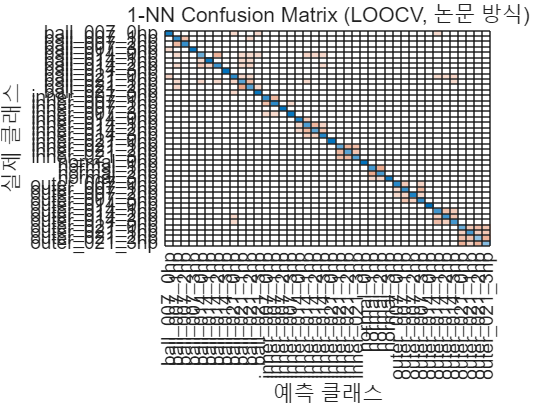


%% === Confusion Matrix Plot ===
figure;
confusionchart(Y, pred_LOO);
title("1-NN Confusion Matrix (LOOCV, 논문 방식)");

%% ============================================================
% 3) SVM — 10-fold Cross Validation + Confusion Matrix (논문 방식)
% ============================================================
disp("=== SVM 10-fold CV 시작 ===");

=== SVM 10-fold CV 시작 ===



cv10 = cvpartition(Y, 'KFold', 10);
SVM_pred = strings(length(Y),1);

% fold별 예측 저장
for fold = 1:cv10.NumTestSets
    trainIdx = training(cv10, fold);
    testIdx  = test(cv10, fold);

    mdl_svm = fitcecoc(X_stat(trainIdx,:), Y(trainIdx));
    SVM_pred(testIdx) = predict(mdl_svm, X_stat(testIdx,:));
end

SVM_pred = categorical(SVM_pred);

% CV accuracy
acc_svm_stat = mean(SVM_pred == Y);
fprintf("SVM (10-fold CV) Accuracy: %.4f (%.2f%%)\n", acc_svm_stat, acc_svm_stat*100);

SVM (10-fold CV) Accuracy: 0.9385 (93.85%)


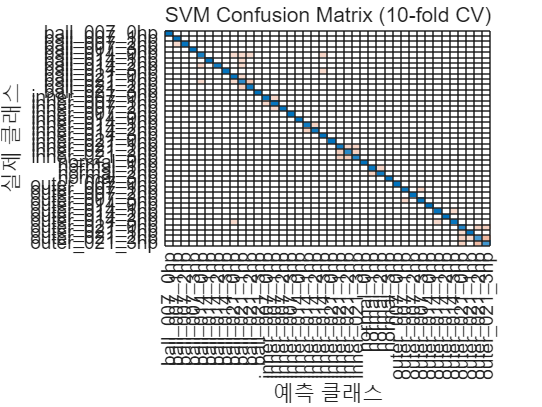


figure;
confusionchart(Y, SVM_pred);
title("SVM Confusion Matrix (10-fold CV)");

%% ============================================================
% 4) Decision Tree — 10-fold CV + Confusion Matrix
% ============================================================
disp("=== Decision Tree 10-fold CV 시작 ===");

=== Decision Tree 10-fold CV 시작 ===



DT_pred = strings(length(Y),1);

for fold = 1:cv10.NumTestSets
    trainIdx = training(cv10, fold);
    testIdx  = test(cv10, fold);

    mdl_tree = fitctree(X_stat(trainIdx,:), Y(trainIdx));
    DT_pred(testIdx) = predict(mdl_tree, X_stat(testIdx,:));
end

DT_pred = categorical(DT_pred);

acc_tree_stat = mean(DT_pred == Y);
fprintf("Decision Tree (10-fold CV) Accuracy: %.4f (%.2f%%)\n", acc_tree_stat*100);

Decision Tree (10-fold CV) Accuracy: 88.2500 (

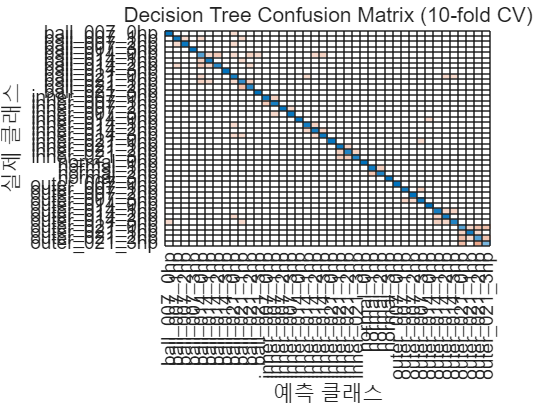


figure;
confusionchart(Y, DT_pred);
title("Decision Tree Confusion Matrix (10-fold CV)");

disp("=== WPT Features (32D) 논문 방식 평가 시작 ===");

=== WPT Features (32D) 논문 방식 평가 시작 ===



%% 1) 데이터 준비
X_wpt = AllFeatures(:, 99:130);
Y = categorical(AllLabels);

% Scaling
mu = mean(X_wpt);
sigma = std(X_wpt);
X_wpt = (X_wpt - mu) ./ sigma;

disp("[1] 1-NN LOOCV");

[1] 1-NN LOOCV



cvLOO = cvpartition(Y, 'LeaveOut');
N = length(Y);

pred_LOO = strings(N,1);

for i = 1:N
    trainIdx = training(cvLOO, i);
    testIdx  = test(cvLOO, i);

    mdl = fitcknn(X_wpt(trainIdx,:), Y(trainIdx), 'NumNeighbors', 1);
    pred_LOO(testIdx) = predict(mdl, X_wpt(testIdx,:));
end

pred_LOO = categorical(pred_LOO);

acc_knn_wpt = mean(pred_LOO == Y);
fprintf("1-NN (LOO) Accuracy: %.2f%%\n", acc_knn_wpt * 100);

1-NN (LOO) Accuracy: 92.70%


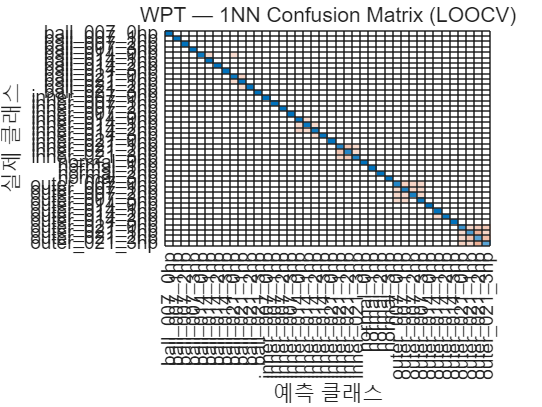


figure; confusionchart(Y, pred_LOO);
title("WPT — 1NN Confusion Matrix (LOOCV)");


disp("[2] SVM 10-fold CV");

[2] SVM 10-fold CV



cv10 = cvpartition(Y, 'KFold', 10);
pred_SVM = strings(N,1);

for fold = 1:cv10.NumTestSets
    trainIdx = training(cv10, fold);
    testIdx  = test(cv10, fold);

    mdl = fitcecoc(X_wpt(trainIdx,:), Y(trainIdx));
    pred_SVM(testIdx) = predict(mdl, X_wpt(testIdx,:));
end

pred_SVM = categorical(pred_SVM);

acc_svm_wpt = mean(pred_SVM == Y);
fprintf("SVM (10-fold) Accuracy: %.2f%%\n", acc_svm_wpt * 100);

SVM (10-fold) Accuracy: 97.70%


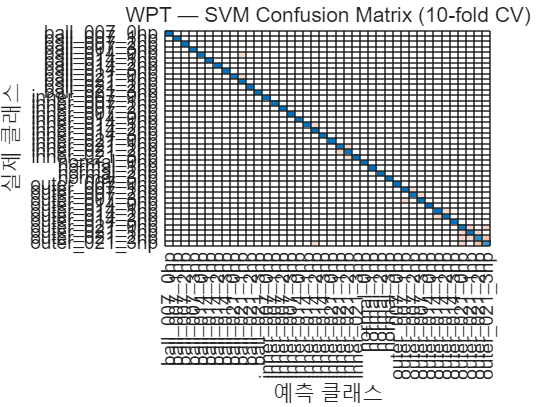


figure; confusionchart(Y, pred_SVM);
title("WPT — SVM Confusion Matrix (10-fold CV)");

disp("[3] Decision Tree 10-fold CV");

[3] Decision Tree 10-fold CV



pred_DT = strings(N,1);

for fold = 1:cv10.NumTestSets
    trainIdx = training(cv10, fold);
    testIdx  = test(cv10, fold);

    mdl = fitctree(X_wpt(trainIdx,:), Y(trainIdx));
    pred_DT(testIdx) = predict(mdl, X_wpt(testIdx,:));
end

pred_DT = categorical(pred_DT);

acc_tree_wpt = mean(pred_DT == Y);
fprintf("Decision Tree (10-fold) Accuracy: %.2f%%\n", acc_tree_wpt * 100);

Decision Tree (10-fold) Accuracy: 92.50%


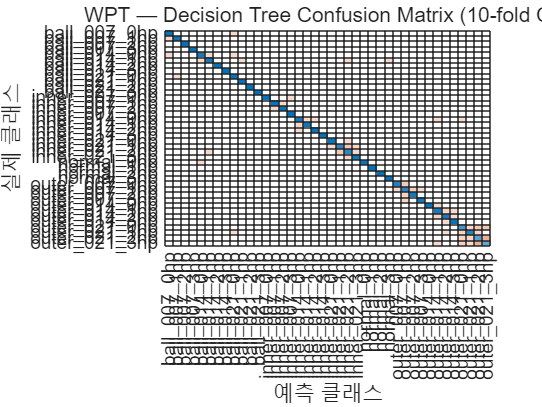


figure; confusionchart(Y, pred_DT);
title("WPT — Decision Tree Confusion Matrix (10-fold CV)");

disp("=== Envelope Features (72D) 논문 방식 평가 시작 ===");

=== Envelope Features (72D) 논문 방식 평가 시작 ===



%% 1) 데이터 준비
X_env = AllFeatures(:, 27:98);
Y = categorical(AllLabels);

mu = mean(X_env);
sigma = std(X_env);
X_env = (X_env - mu) ./ sigma;

N = length(Y);

disp("[1] 1-NN LOOCV");

[1] 1-NN LOOCV



cvLOO = cvpartition(Y, 'LeaveOut');
pred_LOO_env = strings(N,1);

for i = 1:N
    trainIdx = training(cvLOO, i);
    testIdx  = test(cvLOO, i);

    mdl = fitcknn(X_env(trainIdx,:), Y(trainIdx), 'NumNeighbors', 1);
    pred_LOO_env(testIdx) = predict(mdl, X_env(testIdx,:));
end

pred_LOO_env = categorical(pred_LOO_env);

acc_knn_env = mean(pred_LOO_env == Y);
fprintf("1-NN (LOO) Accuracy: %.2f%%\n", acc_knn_env * 100);

1-NN (LOO) Accuracy: 90.65%


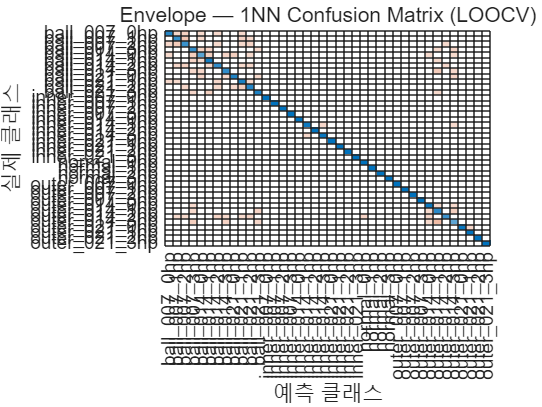


figure; confusionchart(Y, pred_LOO_env);
title("Envelope — 1NN Confusion Matrix (LOOCV)");


disp("[2] SVM 10-fold CV");

[2] SVM 10-fold CV



cv10 = cvpartition(Y, 'KFold', 10);
pred_SVM_env = strings(N,1);

for fold = 1:cv10.NumTestSets
    trainIdx = training(cv10, fold);
    testIdx  = test(cv10, fold);

    mdl = fitcecoc(X_env(trainIdx,:), Y(trainIdx));
    pred_SVM_env(testIdx) = predict(mdl, X_env(testIdx,:));
end

pred_SVM_env = categorical(pred_SVM_env);

acc_svm_env = mean(pred_SVM_env == Y);
fprintf("SVM (10-fold) Accuracy: %.2f%%\n", acc_svm_env * 100);

SVM (10-fold) Accuracy: 98.00%


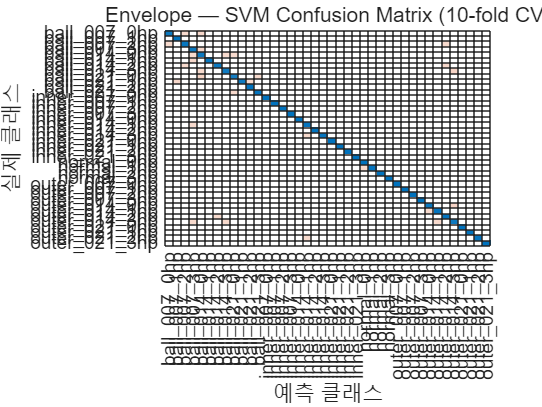


figure; confusionchart(Y, pred_SVM_env);
title("Envelope — SVM Confusion Matrix (10-fold CV)");


disp("[3] Decision Tree 10-fold CV");

[3] Decision Tree 10-fold CV



pred_DT_env = strings(N,1);

for fold = 1:cv10.NumTestSets
    trainIdx = training(cv10, fold);
    testIdx  = test(cv10, fold);

    mdl = fitctree(X_env(trainIdx,:), Y(trainIdx));
    pred_DT_env(testIdx) = predict(mdl, X_env(testIdx,:));
end

pred_DT_env = categorical(pred_DT_env);

acc_tree_env = mean(pred_DT_env == Y);
fprintf("Decision Tree (10-fold) Accuracy: %.2f%%\n", acc_tree_env * 100);

Decision Tree (10-fold) Accuracy: 95.70%


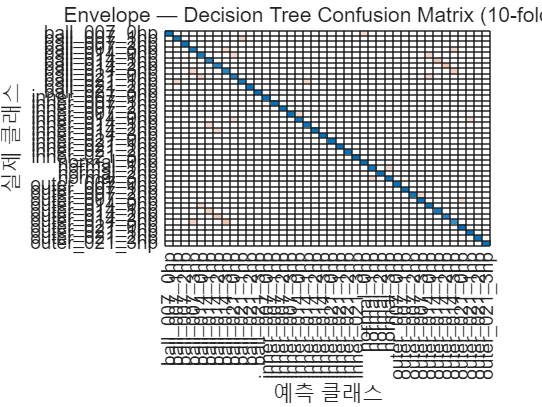


figure; confusionchart(Y, pred_DT_env);
title("Envelope — Decision Tree Confusion Matrix (10-fold CV)");

%% ============================================================
%   CASE 1 — Complete Pool (130 features) 논문 방식 평가
%   - 1-NN  → Leave-One-Out (LOO)
%   - SVM   → 10-fold CV
%   - DTree → 10-fold CV
%   - Confusion Matrix도 CV 기반으로 생성
% ============================================================

disp("=== Complete Pool (130D) 논문 방식 평가 시작 ===");

=== Complete Pool (130D) 논문 방식 평가 시작 ===



%% 1) 데이터 준비
X_cp = AllFeatures(:, 1:130);
Y = categorical(AllLabels);

% Scaling
mu = mean(X_cp);
sigma = std(X_cp);
X_cp = (X_cp - mu) ./ sigma;

N = length(Y);

disp("[1] 1-NN LOOCV");

[1] 1-NN LOOCV



cvLOO = cvpartition(Y, 'LeaveOut');
pred_knn_cp = strings(N,1);

for i = 1:N
    trainIdx = training(cvLOO, i);
    testIdx  = test(cvLOO, i);

    mdl = fitcknn(X_cp(trainIdx,:), Y(trainIdx), 'NumNeighbors', 1);
    pred_knn_cp(testIdx) = predict(mdl, X_cp(testIdx,:));
end

pred_knn_cp = categorical(pred_knn_cp);
acc_knn_cp = mean(pred_knn_cp == Y);

fprintf("1-NN (LOO) Accuracy: %.2f%%\n", acc_knn_cp * 100);

1-NN (LOO) Accuracy: 99.70%


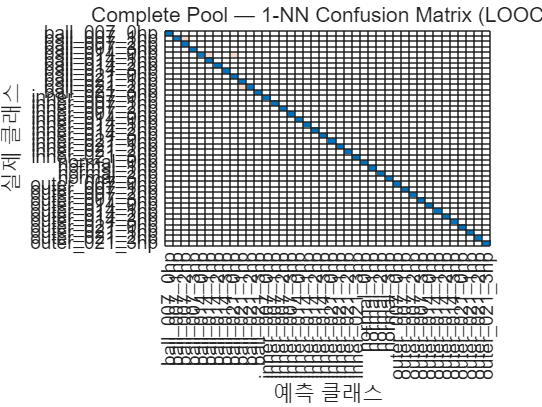


figure;
confusionchart(Y, pred_knn_cp);
title("Complete Pool — 1-NN Confusion Matrix (LOOCV)");


disp("[2] SVM 10-fold CV");

[2] SVM 10-fold CV



cv10 = cvpartition(Y, 'KFold', 5);
pred_svm_cp = strings(N,1);

for fold = 1:cv10.NumTestSets
    trainIdx = training(cv10, fold);
    testIdx  = test(cv10, fold);

    mdl = fitcecoc(X_cp(trainIdx,:), Y(trainIdx));
    pred_svm_cp(testIdx) = predict(mdl, X_cp(testIdx,:));
end

pred_svm_cp = categorical(pred_svm_cp);
acc_svm_cp = mean(pred_svm_cp == Y);

fprintf("SVM (10-fold) Accuracy: %.2f%%\n", acc_svm_cp * 100);

SVM (10-fold) Accuracy: 99.85%


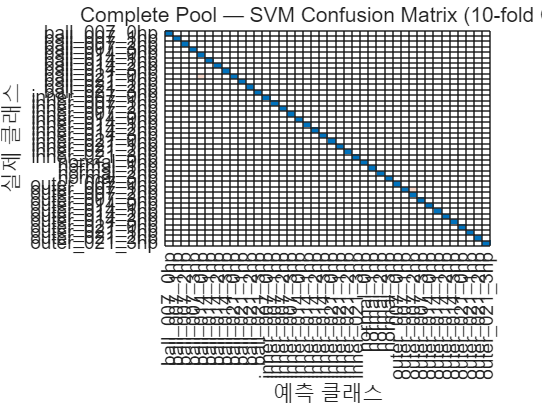


figure;
confusionchart(Y, pred_svm_cp);
title("Complete Pool — SVM Confusion Matrix (10-fold CV)");


disp("[3] Decision Tree 10-fold CV");

[3] Decision Tree 10-fold CV



pred_tree_cp = strings(N,1);

for fold = 1:cv10.NumTestSets
    trainIdx = training(cv10, fold);
    testIdx  = test(cv10, fold);

    mdl = fitctree(X_cp(trainIdx,:), Y(trainIdx));
    pred_tree_cp(testIdx) = predict(mdl, X_cp(testIdx,:));
end

pred_tree_cp = categorical(pred_tree_cp);
acc_tree_cp = mean(pred_tree_cp == Y);

fprintf("Decision Tree (10-fold) Accuracy: %.2f%%\n", acc_tree_cp * 100);

Decision Tree (10-fold) Accuracy: 99.05%


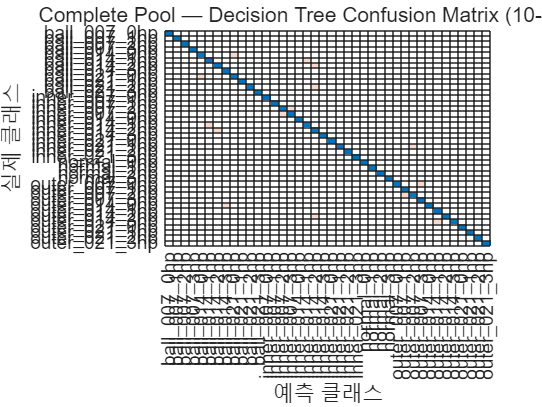


figure;
confusionchart(Y, pred_tree_cp);
title("Complete Pool — Decision Tree Confusion Matrix (10-fold CV)");

%% === CASE 1 Accuracy Summary Table ===

% Statistical
STAT_KNN  = acc_knn_stat  * 100;
STAT_SVM  = acc_svm_stat  * 100;
STAT_TREE = acc_tree_stat * 100;

% Envelope
ENV_KNN  = acc_knn_env  * 100;
ENV_SVM  = acc_svm_env  * 100;
ENV_TREE = acc_tree_env * 100;

% WPT
WPT_KNN  = acc_knn_wpt  * 100;
WPT_SVM  = acc_svm_wpt  * 100;
WPT_TREE = acc_tree_wpt * 100;

% Complete Pool
CP_KNN  = acc_knn_cp  * 100;
CP_SVM  = acc_svm_cp  * 100;
CP_TREE = acc_tree_cp * 100;

% === Summary Table ===
AccuracyTable = table( ...
    [STAT_KNN; ENV_KNN; WPT_KNN; CP_KNN], ...
    [STAT_SVM; ENV_SVM; WPT_SVM; CP_SVM], ...
    [STAT_TREE; ENV_TREE; WPT_TREE; CP_TREE], ...
    'VariableNames', {'KNN', 'SVM', 'DecisionTree'}, ...
    'RowNames', {'Statistical', 'Envelope', 'WPT', 'CompletePool'} ...
);

disp("=== CASE 1 Accuracy Summary (%) ===")

=== CASE 1 Accuracy Summary (%) ===


disp(AccuracyTable)

                     KNN      SVM     DecisionTree
                    _____    _____    ____________

    Statistical     73.55    93.85       88.25    
    Envelope        90.65       98        95.7    
    WPT              92.7     97.7        92.5    
    CompletePool     99.7    99.85       99.05    



## Feature Selection

%% === STEP 1: Train/Test Split ===
rng(1);

cv = cvpartition(AllLabels, 'Holdout', 0.2, 'Stratify', true);

Xtrain_all = AllFeatures(training(cv), :);
Ytrain_all = categorical(AllLabels(training(cv)));

Xtest_all  = AllFeatures(test(cv), :);
Ytest_all  = categorical(AllLabels(test(cv)));

disp("Train/Test split 완료");

Train/Test split 완료




%% === STEP 2: 전체 Scaling ===
X = AllFeatures;
Y = categorical(AllLabels);

mu = mean(X);
sigma = std(X);
X = (X - mu) ./ sigma;

numFeat = size(X,2);


%% === STEP 3: 10-fold CV for SFS ===
cvKF = cvpartition(Y,'KFold',10);


%% === STEP 4: SFS Evaluator (1NN) 단 1번 ===
disp("=== SFS 시작 (Evaluator = 1NN) ===");

=== SFS 시작 (Evaluator = 1NN) ===



evaluate = @(mask) ...
    1 - kfoldLoss( ...
            crossval( ...
                fitcknn(X(:,mask), Y, 'NumNeighbors',1), ...
                'cvpartition', cvKF ...
            ) ...
        );

[inmodel_SFS, selectedOrder_SFS] = SFS_core(X, Y, numFeat, cvKF, evaluate);


---- SFS Iteration 1 시작 ----
 Iter 1 | Feature 1/130 (0.8%) | Acc = 0.3450
 Iter 1 | Feature 2/130 (1.5%) | Acc = 0.3315
 Iter 1 | Feature 3/130 (2.3%) | Acc = 0.1470
 Iter 1 | Feature 4/130 (3.1%) | Acc = 0.0850
 Iter 1 | Feature 5/130 (3.8%) | Acc = 0.2245
 Iter 1 | Feature 6/130 (4.6%) | Acc = 0.1020
 Iter 1 | Feature 7/130 (5.4%) | Acc = 0.1165
 Iter 1 | Feature 8/130 (6.2%) | Acc = 0.1495
 Iter 1 | Feature 9/130 (6.9%) | Acc = 0.1945
 Iter 1 | Feature 10/130 (7.7%) | Acc = 0.3045
 Iter 1 | Feature 11/130 (8.5%) | Acc = 0.0235
 Iter 1 | Feature 12/130 (9.2%) | Acc = 0.2150
 Iter 1 | Feature 13/130 (10.0%) | Acc = 0.2150
 Iter 1 | Feature 14/130 (10.8%) | Acc = 0.3800
 Iter 1 | Feature 15/130 (11.5%) | Acc = 0.3440
 Iter 1 | Feature 16/130 (12.3%) | Acc = 0.1440
 Iter 1 | Feature 17/130 (13.1%) | Acc = 0.0860
 Iter 1 | Feature 18/130 (13.8%) | Acc = 0.1700
 Iter 1 | Feature 19/130 (14.6%) | Acc = 0.0890
 Iter 1 | Feature 20/130 (15.4%) | Acc = 0.0995
 Iter 1 | Feature 21/130 (16.2%


disp("선택된 feature 개수:");

선택된 feature 개수:


disp(sum(inmodel_SFS));

    10



disp("선택된 feature index:");

선택된 feature index:


disp(find(inmodel_SFS));

     2    14    22    26    27    41    51   101   114   117





%% === STEP 5: Train/Test Scaling 후 Selected Feature 적용 ===
Xtrain_sel = (Xtrain_all - mu) ./ sigma;
Xtest_sel  = (Xtest_all  - mu) ./ sigma;

Xtrain_sel = Xtrain_sel(:, inmodel_SFS);
Xtest_sel  = Xtest_sel(:, inmodel_SFS);


%% ============================================================
%   (A) 1-NN 평가
%% ============================================================
disp("=== (A) 1-NN 평가 ===");

=== (A) 1-NN 평가 ===



cvLOO = cvpartition(Ytrain_all, 'LeaveOut');
mdl_knn = fitcknn(Xtrain_sel, Ytrain_all, 'NumNeighbors',1);

looLoss = kfoldLoss(crossval(mdl_knn,'cvpartition',cvLOO));
looAcc = 1 - looLoss;

fprintf("1-NN LOOCV Accuracy = %.2f%%\n", looAcc*100);

1-NN LOOCV Accuracy = 99.81%



Ypred_knn = predict(mdl_knn, Xtest_sel);
testAcc_knn = mean(Ypred_knn == Ytest_all);
fprintf("1-NN Test Accuracy = %.2f%%\n", testAcc_knn*100);

1-NN Test Accuracy = 100.00%


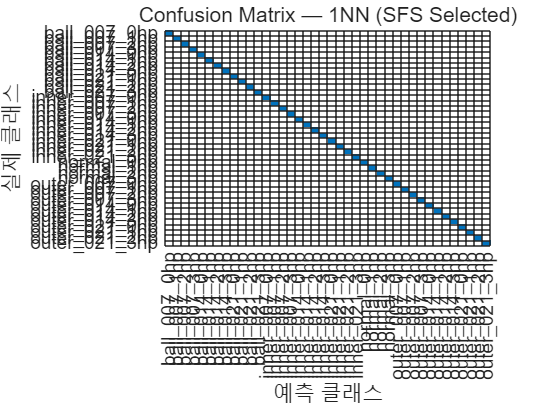


figure; confusionchart(Ytest_all, Ypred_knn);
title("Confusion Matrix — 1NN (SFS Selected)");




%% ============================================================
%   (B) SVM 평가
%% ============================================================
disp("=== (B) SVM 평가 ===");

=== (B) SVM 평가 ===



t = templateSVM('KernelFunction','rbf','Standardize',true);
mdl_svm = fitcecoc(Xtrain_sel, Ytrain_all,'Learners',t);

cv10 = crossval(mdl_svm,'KFold',10);
svmAcc = 1 - kfoldLoss(cv10);

fprintf("SVM 10-fold CV Accuracy = %.2f%%\n", svmAcc*100);

SVM 10-fold CV Accuracy = 91.75%



Ypred_svm = predict(mdl_svm, Xtest_sel);
testAcc_svm = mean(Ypred_svm == Ytest_all);
fprintf("SVM Test Accuracy = %.2f%%\n", testAcc_svm*100);

SVM Test Accuracy = 92.75%


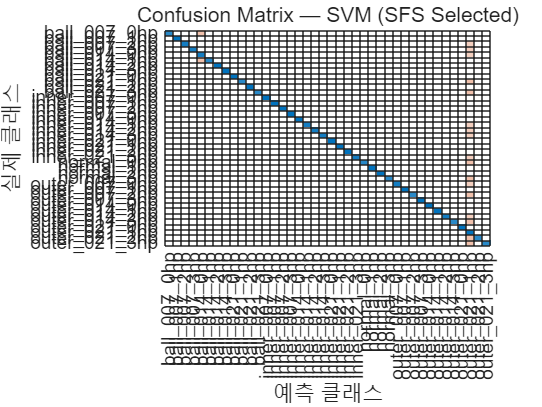


figure; confusionchart(Ytest_all, Ypred_svm);
title("Confusion Matrix — SVM (SFS Selected)");




%% ============================================================
%   (C) Decision Tree 평가
%% ============================================================
disp("=== (C) Decision Tree 평가 ===");

=== (C) Decision Tree 평가 ===



tree = fitctree(Xtrain_sel, Ytrain_all);
cvTree = crossval(tree,'KFold',10);

treeAcc = 1 - kfoldLoss(cvTree);
fprintf("Decision Tree 10-fold CV Accuracy = %.2f%%\n", treeAcc*100);

Decision Tree 10-fold CV Accuracy = 98.62%



Ypred_tree = predict(tree, Xtest_sel);
testAcc_tree = mean(Ypred_tree == Ytest_all);
fprintf("Decision Tree Test Accuracy = %.2f%%\n", testAcc_tree*100);

Decision Tree Test Accuracy = 99.00%


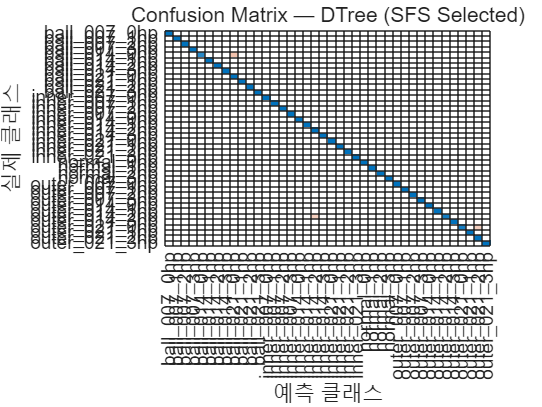


figure; confusionchart(Ytest_all, Ypred_tree);
title("Confusion Matrix — DTree (SFS Selected)");



%% ============================================================
%   SFS Function Definition (Sequential Forward Selection)
%   - Evaluator(evaluate)만 바꾸면 재사용 가능
%   - X, Y, numFeat, cvKF, evaluate를 입력으로 받음
%% ============================================================
function [inmodel_SFS, selectedOrderSFS] = SFS_core(X, Y, numFeat, cvKF, evaluate)

selected = false(1, numFeat);   % 초기: 아무 feature도 없음
bestAcc = -inf;
selectedOrderSFS = [];

ITER = 0;
tic;

improved = true;

while improved
    improved = false;
    ITER = ITER + 1;

    fprintf("\n---- SFS Iteration %d 시작 ----\n", ITER);
    iterStart = tic;

    bestAddFeat = -1;
    bestAddAcc = -inf;

    for f = 1:numFeat
        if selected(f)
            continue;
        end

        tryMask = selected;
        tryMask(f) = true;

        acc = evaluate(tryMask);

        pct = (f / numFeat) * 100;
        fprintf(" Iter %d | Feature %d/%d (%.1f%%) | Acc = %.4f\n", ...
                 ITER, f, numFeat, pct, acc);

        if acc > bestAddAcc
            bestAddAcc = acc;
            bestAddFeat = f;
        end
    end

    iterTime = toc(iterStart);
    fprintf("Iter %d 완료. 소요시간 = %.1f sec.\n", ITER, iterTime);

    if bestAddAcc > bestAcc
        selected(bestAddFeat) = true;
        bestAcc = bestAddAcc;
        improved = true;

        selectedOrderSFS(end+1) = bestAddFeat;

        fprintf(" → 선택됨: feature %d | 새 BestAcc = %.4f\n", ...
                bestAddFeat, bestAcc);
    end
end

totalTime = toc;
fprintf("\n=== SFS 완료 (총 %.1f sec) ===\n", totalTime);

inmodel_SFS = selected;

end


%% ============================================================
%   PCA 기반 Feature Extraction (논문 Experiment 5)
%   - 기존 AllFeatures (130D) 사용
%   - PCA → reduced features
%   - 1NN(LOOCV), SVM(10-fold) 평가
% ============================================================

disp("=== PCA Experiment 시작 ===");

=== PCA Experiment 시작 ===



X = AllFeatures;
Y = categorical(AllLabels);

%% ---- Scaling (Z-score) ----
mu = mean(X);
sigma = std(X);
X_scaled = (X - mu) ./ sigma;

%% ---- PCA 학습 ----
[coeff, score, latent, tsquared, explained] = pca(X_scaled);


disp("PCA 완료 — explained variance 확인");

PCA 완료 — explained variance 확인


cumulative_explained = cumsum(explained);
disp(table((1:130)', explained, cumulative_explained, ...
    'VariableNames', {'PC','ExplainedVar','Cumulative'}));

    PC     ExplainedVar    Cumulative
    ___    ____________    __________

      1         32.254       32.254  
      2          13.78       46.035  
      3         10.253       56.287  
      4         8.5768       64.864  
      5         6.8752       71.739  
      6         3.6815       75.421  
      7         2.6447       78.066  
      8         2.0772       80.143  
      9         1.9861       82.129  
     10         1.7126       83.842  
     11         1.4182        85.26  
     12         1.3446       86.604  
     13         1.0514       87.656  
     14        0.86705       88.523  
     15        0.79629       89.319  
     16        0.76612       90.085  
     17        0.73568       90.821  
     18        0.71628       91.537  
     19        0.66326         92.2  
     20        0.58549       92.786  
     21        0.55765       93.344  
     22        0.50748       93.851  
     23         0.4694        94.32  
     24        0.43546       94.756  
     25    

%% ============================================================
%   PCA 차원 설정 (논문식)
% ============================================================
pca_dims = [2 5 10 20 30 50 80 130];   % 원하는 만큼 조절 가능

result_knn = zeros(length(pca_dims),1);
result_svm = zeros(length(pca_dims),1);
result_tree = zeros(length(pca_dims),1);   % ★ 추가됨

N = length(Y);

%% ============================================================
%   Evaluate PCA features for each dimension
% ============================================================
for i = 1:length(pca_dims)
    d = pca_dims(i);
    fprintf("\n===== PCA Dimension = %d =====\n", d);

    X_pca = score(:,1:d);

    %% ---- (1) 1-NN LOOCV ----
    cvLOO = cvpartition(Y, 'LeaveOut');
    pred_knn = strings(N,1);

    for k = 1:N
        trainIdx = training(cvLOO, k);
        testIdx  = test(cvLOO, k);

        mdl_knn = fitcknn(X_pca(trainIdx,:), Y(trainIdx), 'NumNeighbors', 1);
        pred_knn(testIdx) = predict(mdl_knn, X_pca(testIdx,:));
    end

    pred_knn = categorical(pred_knn);
    acc_knn = mean(pred_knn == Y);
    result_knn(i) = acc_knn * 100;

    fprintf("1-NN LOOCV Accuracy = %.2f%%\n", acc_knn*100);


    %% ---- (2) SVM 10-fold CV ----
    cv10 = cvpartition(Y, 'KFold', 10);
    pred_svm = strings(N,1);

    for fold = 1:cv10.NumTestSets
        trainIdx = training(cv10, fold);
        testIdx  = test(cv10, fold);

        mdl_svm = fitcecoc(X_pca(trainIdx,:), Y(trainIdx), ...
                           'Learners', templateSVM('KernelFunction','rbf'));

        pred_svm(testIdx) = predict(mdl_svm, X_pca(testIdx,:));
    end

    pred_svm = categorical(pred_svm);
    acc_svm = mean(pred_svm == Y);
    result_svm(i) = acc_svm * 100;

    fprintf("SVM 10-fold CV Accuracy = %.2f%%\n", acc_svm*100);


    %% ---- (3) Decision Tree 10-fold CV ----  ★ 추가됨
    pred_tree = strings(N,1);

    for fold = 1:cv10.NumTestSets
        trainIdx = training(cv10, fold);
        testIdx  = test(cv10, fold);

        mdl_tree = fitctree(X_pca(trainIdx,:), Y(trainIdx));
        pred_tree(testIdx) = predict(mdl_tree, X_pca(testIdx,:));
    end

    pred_tree = categorical(pred_tree);
    acc_tree = mean(pred_tree == Y);
    result_tree(i) = acc_tree * 100;

    fprintf("Decision Tree 10-fold CV Accuracy = %.2f%%\n", acc_tree*100);

end


===== PCA Dimension = 2 =====


1-NN LOOCV Accuracy = 56.75%


SVM 10-fold CV Accuracy = 65.45%


Decision Tree 10-fold CV Accuracy = 58.50%



===== PCA Dimension = 5 =====


1-NN LOOCV Accuracy = 95.60%


SVM 10-fold CV Accuracy = 94.65%


Decision Tree 10-fold CV Accuracy = 90.20%



===== PCA Dimension = 10 =====


1-NN LOOCV Accuracy = 99.15%


SVM 10-fold CV Accuracy = 83.90%


Decision Tree 10-fold CV Accuracy = 94.20%



===== PCA Dimension = 20 =====


1-NN LOOCV Accuracy = 99.50%


SVM 10-fold CV Accuracy = 63.80%


Decision Tree 10-fold CV Accuracy = 95.35%



===== PCA Dimension = 30 =====


1-NN LOOCV Accuracy = 99.75%


SVM 10-fold CV Accuracy = 51.20%


Decision Tree 10-fold CV Accuracy = 95.20%



===== PCA Dimension = 50 =====


1-NN LOOCV Accuracy = 99.75%


SVM 10-fold CV Accuracy = 42.85%


Decision Tree 10-fold CV Accuracy = 95.05%



===== PCA Dimension = 80 =====


1-NN LOOCV Accuracy = 99.70%


SVM 10-fold CV Accuracy = 41.80%


Decision Tree 10-fold CV Accuracy = 95.20%



===== PCA Dimension = 130 =====


1-NN LOOCV Accuracy = 99.70%


SVM 10-fold CV Accuracy = 41.45%


Decision Tree 10-fold CV Accuracy = 95.45%




%% ============================================================
%   결과 테이블 출력 (논문 Table IX + Decision Tree 확장)
% ============================================================

ResultTable = table(pca_dims', result_knn, result_svm, result_tree, ...
    'VariableNames', {'PCA_Dimension','KNN_Accuracy','SVM_Accuracy','DTree_Accuracy'});

disp("=== PCA 결과 테이블 ===");

=== PCA 결과 테이블 ===


disp(ResultTable);

    PCA_Dimension    KNN_Accuracy    SVM_Accuracy    DTree_Accuracy
    _____________    ____________    ____________    ______________

           2            56.75           65.45             58.5     
           5             95.6           94.65             90.2     
          10            99.15            83.9             94.2     
          20             99.5            63.8            95.35     
          30            99.75            51.2             95.2     
          50            99.75           42.85            95.05     
          80             99.7            41.8             95.2     
         130             99.7           41.45            95.45     



=== PCA Experiment 시작 ===


'X_scaled'은(는) 인식할 수 없는 함수 또는 변수입니다.